# The goal for this version is to introduce Phase variant LGN input

LGN is still fake, but will add more realistic factors...

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\GitHub\NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo061921/'];
addpath(SaveFolder)

DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_E = n_E_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnEex.X,NnEex.Y] = V1Field_Generation(N_HC+2,1:Nex_E,'e');
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');


## Get a mapping between original and extended spatial indexs

% From original to extended
EMap_Ori2Ext = find(NnEex.X>n_E_HC & NnEex.X<=4*n_E_HC ...
                  & NnEex.Y>n_E_HC & NnEex.Y<=4*n_E_HC);
IMap_Ori2Ext = find(NnIex.X>n_I_HC & NnIex.X<=4*n_I_HC ...
                  & NnIex.Y>n_I_HC & NnIex.Y<=4*n_I_HC);
% from extended back to original: fold
% E
EMap_Ext2Ori = zeros(size(NnEex.X));
EMap_Ext2Ori(EMap_Ori2Ext) = 1:N_E;
CenterEHC = find(NnE.X>1*n_E_HC & NnE.X<=2*n_E_HC ...
               & NnE.Y>1*n_E_HC & NnE.Y<=2*n_E_HC);
CenterEHCRow = find(NnE.Y>1*n_E_HC & NnE.Y<=2*n_E_HC);
CenterEHCCol = find(NnE.X>1*n_E_HC & NnE.X<=2*n_E_HC);
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHC; % LL corner
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHC; % RL corner
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHC; % LH corner
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHC; % RH corner
EMap_Ext2Ori(NnEex.X>1*n_E_HC & NnEex.X<=4*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHCRow; % Low
EMap_Ext2Ori(NnEex.X>1*n_E_HC & NnEex.X<=4*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHCRow;    % High
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>1*n_E_HC & NnEex.Y<=4*n_E_HC) = CenterEHCCol; % Left
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>1*n_E_HC & NnEex.Y<=4*n_E_HC) = CenterEHCCol;    % Right
% I
IMap_Ext2Ori = zeros(size(NnIex.X));
IMap_Ext2Ori(IMap_Ori2Ext) = 1:N_I;
CenterIHC = find(NnI.X>1*n_I_HC & NnI.X<=2*n_I_HC ...
               & NnI.Y>1*n_I_HC & NnI.Y<=2*n_I_HC);
CenterIHCRow = find(NnI.Y>1*n_I_HC & NnI.Y<=2*n_I_HC);
CenterIHCCol = find(NnI.X>1*n_I_HC & NnI.X<=2*n_I_HC);
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHC; % LL corner
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHC; % RL corner
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHC; % LH corner
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHC; % RH corner
IMap_Ext2Ori(NnIex.X>1*n_I_HC & NnIex.X<=4*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHCRow; % Low
IMap_Ext2Ori(NnIex.X>1*n_I_HC & NnIex.X<=4*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHCRow; % High
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>1*n_I_HC & NnIex.Y<=4*n_I_HC) = CenterIHCCol; % Left
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>1*n_I_HC & NnIex.Y<=4*n_I_HC) = CenterIHCCol; % Right
% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary

C_EE_Fix_Bd = ConnectionMat_Fix_Boundary(N_E,NnEex,Size_E, EMap_Ori2Ext,...currentVec(2)^2
                                         N_E,NnEex,Size_E, EMap_Ext2Ori,...
                                         Peak_EE,SD_E,Dist_LB,1, round(N_EE));

Elapsed time is 19.052005 seconds.



C_EI_Fix_Bd = ConnectionMat_Fix_Boundary(N_E,NnEex,Size_E, EMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,0, round(N_EI));

Elapsed time is 6.852750 seconds.



C_IE_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_E,NnEex,Size_E, EMap_Ext2Ori,...
                                         Peak_I,SD_E,Dist_LB,0, round(N_IE));

Elapsed time is 8.646548 seconds.



C_II_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.303974 seconds.



CMatAll = struct('C_EE_Fix_Bd',C_EE_Fix_Bd,...
                 'C_EI_Fix_Bd',C_EI_Fix_Bd,...
                 'C_IE_Fix_Bd',C_IE_Fix_Bd,...
                 'C_II_Fix_Bd',C_II_Fix_Bd);

### Checking presyn neurons to goundary neurons. Can jump

EX = 150; EY = 150;
EInd = find(NnE.X == EX & NnE.Y == EY);
PreEInd = find(C_EE_Fix_Bd(EInd,:));
PreIInd = find(C_EI_Fix_Bd(EInd,:));

figure
subplot 221
hold on
imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnE.X(PreEInd),NnE.Y(PreEInd), 'r.')
scatter(EX,EY,'kO')
set(gca,'YDir','normal')
axis([0 n_E_HC * N_HC 0 n_E_HC * N_HC])
title('PreE to E')

subplot 222
hold on
imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to E')

IX = 1; IY = 15;
IInd = find(NnE.X == IX & NnE.Y == IY);
PreEInd = find(C_IE_Fix_Bd(IInd,:));
PreIInd = find(C_II_Fix_Bd(IInd,:));

subplot 223
hold on
imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnE.X(PreEInd),NnE.Y(PreEInd), 'r.')
scatter(IX,IY,'kO')
set(gca,'YDir','normal')
axis([0 n_E_HC * N_HC 0 n_E_HC * N_HC])
title('PreE to I')

subplot 224
hold on
imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to I')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Placeholder for old BG session...

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 2; % 2Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFR = [90 67.5 45 67.5,    0  22.5 45 22.5] *4/1e3 * StimulusFac;
lambda_EOn_drive  = PhaseFR(OD_E)';
lambda_EOff_drive = PhaseFR(OD_E+ODNum)';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive = 45 *4/1e3 * StimulusFac;
lambda_I_drive = 45 *4/1e3 * StimulusFac;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);


Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFR(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT_Bdr' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end
save([SaveFolder,'DriveWkSp_FixPreSynN_LowIto_Conn.mat'],'CMatAll');

### Plot Spatial maps: load data

% read data, and get spike and mV

SampleInd = 2

FrENow = 18.2655

FrINow = 69.9988

Elapsed time is 2.603841 seconds.


SampleInd = 3

FrENow = 16.5310

FrINow = 68.5166

Elapsed time is 4.434173 seconds.


SampleInd = 4

FrENow = 16.9265

FrINow = 70.7111

Elapsed time is 6.948333 seconds.


SampleInd = 5

FrENow = 15.5708

FrINow = 68.1304

Elapsed time is 8.768140 seconds.


SampleInd = 6

FrENow = 16.6469

FrINow = 70.6833

Elapsed time is 11.269789 seconds.


SampleInd = 7

FrENow = 16.1088

FrINow = 69.6381

Elapsed time is 13.119386 seconds.


SampleInd = 8

FrENow = 15.9076

FrINow = 69.0531

Elapsed time is 15.543261 seconds.


SampleInd = 9

FrENow = 16.8534

FrINow = 71.2429

Elapsed time is 17.399662 seconds.


SampleInd = 10

FrENow = 15.3940

FrINow = 67.7442

Elapsed time is 19.788005 seconds.


SampleInd = 11

FrENow = 16.1035

FrINow = 69.2265

Elapsed time is 21.606188 seconds.


SampleInd = 12

FrENow = 16.2224

FrINow = 69.7052

Elapsed time is 24.067876 seconds.


SampleInd = 13

FrENow = 16.4982

FrINow = 70.5214

Elapsed time is 25.895984 seconds.


SampleInd = 14

FrENow = 16.0692

FrINow = 69.4601

Elapsed time is 28.331571 seconds.


SampleInd = 15

FrENow = 15.4230

FrINow = 67.4691

Elapsed time is 30.144327 seconds.


SampleInd = 16

FrENow = 16.2651

FrINow = 69.7722

Elapsed time is 32.509107 seconds.


SampleInd = 17

FrENow = 15.9023

FrINow = 69.0184

Elapsed time is 34.357468 seconds.


SampleInd = 18

FrENow = 16.4114

FrINow = 70.2694

Elapsed time is 36.817437 seconds.


SampleInd = 19

FrENow = 15.9777

FrINow = 69.0531

Elapsed time is 38.651463 seconds.


SampleInd = 20

FrENow = 15.7514

FrINow = 68.7085

Elapsed time is 41.022800 seconds.


SampleInd = 21

FrENow = 16.5645

FrINow = 70.6879

Elapsed time is 42.797096 seconds.


Elapsed time is 42.797967 seconds.


SampleInd = 22

FrENow = 15.8863

FrINow = 68.3640

Elapsed time is 2.398207 seconds.


SampleInd = 23

FrENow = 16.4571

FrINow = 70.8799

Elapsed time is 4.209785 seconds.


SampleInd = 24

FrENow = 16.3466

FrINow = 69.9248

Elapsed time is 6.578561 seconds.


SampleInd = 25

FrENow = 15.1699

FrINow = 66.8285

Elapsed time is 8.315117 seconds.


SampleInd = 26

FrENow = 17.3876

FrINow = 72.8940

Elapsed time is 10.866257 seconds.


SampleInd = 27

FrENow = 15.1760

FrINow = 67.1453

Elapsed time is 12.672370 seconds.


SampleInd = 28

FrENow = 15.7849

FrINow = 68.2807

Elapsed time is 15.043531 seconds.


SampleInd = 29

FrENow = 16.2932

FrINow = 69.9110

Elapsed time is 16.898766 seconds.


SampleInd = 30

FrENow = 16.5638

FrINow = 70.2763

Elapsed time is 19.282730 seconds.


SampleInd = 31

FrENow = 15.4931

FrINow = 67.8044

Elapsed time is 21.039647 seconds.


SampleInd = 32

FrENow = 16.7680

FrINow = 70.9747

Elapsed time is 23.512113 seconds.


SampleInd = 33

FrENow = 16.1225

FrINow = 69.4115

Elapsed time is 25.300497 seconds.


SampleInd = 34

FrENow = 15.6302

FrINow = 68.5813

Elapsed time is 27.713531 seconds.


SampleInd = 35

FrENow = 16.1713

FrINow = 69.5687

Elapsed time is 29.525595 seconds.


SampleInd = 36

FrENow = 16.2925

FrINow = 69.9711

Elapsed time is 31.985268 seconds.


SampleInd = 37

FrENow = 16.5516

FrINow = 70.5261

Elapsed time is 33.807865 seconds.


SampleInd = 38

FrENow = 15.9960

FrINow = 69.5595

Elapsed time is 36.258805 seconds.


SampleInd = 39

FrENow = 15.9465

FrINow = 69.1872

Elapsed time is 38.065465 seconds.


SampleInd = 40

FrENow = 16.2612

FrINow = 69.8971

Elapsed time is 40.512323 seconds.


SampleInd = 41

FrENow = 16.0639

FrINow = 69.2843

Elapsed time is 42.327633 seconds.


Elapsed time is 42.328366 seconds.


SampleInd = 42

FrENow = 16.5394

FrINow = 70.6232

Elapsed time is 2.450569 seconds.


SampleInd = 43

FrENow = 15.8680

FrINow = 69.0114

Elapsed time is 4.254234 seconds.


SampleInd = 44

FrENow = 17.1224

FrINow = 71.8326

Elapsed time is 6.723205 seconds.


SampleInd = 45

FrENow = 16.5059

FrINow = 70.5145

Elapsed time is 8.554228 seconds.


SampleInd = 46

FrENow = 16.4144

FrINow = 70.3411

Elapsed time is 11.045078 seconds.


SampleInd = 47

FrENow = 15.7811

FrINow = 68.6299

Elapsed time is 12.832697 seconds.


SampleInd = 48

FrENow = 16.1256

FrINow = 69.5109

Elapsed time is 15.254298 seconds.


SampleInd = 49

FrENow = 15.8893

FrINow = 69.0091

Elapsed time is 17.058029 seconds.


SampleInd = 50

FrENow = 16.6461

FrINow = 70.7735

Elapsed time is 19.526803 seconds.


SampleInd = 51

FrENow = 15.5929

FrINow = 68.0680

Elapsed time is 21.359788 seconds.


SampleInd = 52

FrENow = 16.0098

FrINow = 69.1248

Elapsed time is 23.809170 seconds.


SampleInd = 53

FrENow = 16.7383

FrINow = 70.9886

Elapsed time is 25.671920 seconds.


SampleInd = 54

FrENow = 15.5822

FrINow = 68.0125

Elapsed time is 28.002880 seconds.


SampleInd = 55

FrENow = 16.3161

FrINow = 69.8370

Elapsed time is 29.877287 seconds.


SampleInd = 56

FrENow = 16.4327

FrINow = 70.3180

Elapsed time is 32.280367 seconds.


SampleInd = 57

FrENow = 16.5089

FrINow = 70.5238

Elapsed time is 34.139849 seconds.


SampleInd = 58

FrENow = 15.6843

FrINow = 68.5443

Elapsed time is 36.617440 seconds.


SampleInd = 59

FrENow = 16.0905

FrINow = 69.1271

Elapsed time is 38.413968 seconds.


SampleInd = 60

FrENow = 16.6575

FrINow = 71.3308

Elapsed time is 40.909168 seconds.


SampleInd = 61

FrENow = 15.6455

FrINow = 68.4842

Elapsed time is 42.778914 seconds.


Elapsed time is 42.779685 seconds.


SampleInd = 62

FrENow = 16.0921

FrINow = 69.1502

Elapsed time is 2.433907 seconds.


SampleInd = 63

FrENow = 16.4480

FrINow = 70.3295

Elapsed time is 4.311845 seconds.


SampleInd = 64

FrENow = 16.2986

FrINow = 69.6728

Elapsed time is 6.737130 seconds.


SampleInd = 65

FrENow = 16.3352

FrINow = 70.3365

Elapsed time is 8.605536 seconds.


SampleInd = 66

FrENow = 15.4138

FrINow = 67.5754

Elapsed time is 10.970200 seconds.


SampleInd = 67

FrENow = 16.5615

FrINow = 70.5885

Elapsed time is 12.766346 seconds.


SampleInd = 68

FrENow = 16.4258

FrINow = 70.0428

Elapsed time is 15.187097 seconds.


SampleInd = 69

FrENow = 15.8604

FrINow = 68.8912

Elapsed time is 16.935761 seconds.


SampleInd = 70

FrENow = 16.2445

FrINow = 69.6265

Elapsed time is 19.419675 seconds.


SampleInd = 71

FrENow = 15.8611

FrINow = 68.7501

Elapsed time is 21.227964 seconds.


SampleInd = 72

FrENow = 16.2094

FrINow = 69.4739

Elapsed time is 23.731539 seconds.


SampleInd = 73

FrENow = 16.1462

FrINow = 69.3884

Elapsed time is 25.563815 seconds.


SampleInd = 74

FrENow = 15.7926

FrINow = 68.2738

Elapsed time is 28.010610 seconds.


SampleInd = 75

FrENow = 16.0471

FrINow = 68.8843

Elapsed time is 29.759129 seconds.


SampleInd = 76

FrENow = 16.8214

FrINow = 70.7827

Elapsed time is 32.182982 seconds.


SampleInd = 77

FrENow = 16.0380

FrINow = 69.5387

Elapsed time is 34.016843 seconds.


SampleInd = 78

FrENow = 15.7125

FrINow = 68.7640

Elapsed time is 36.449826 seconds.


SampleInd = 79

FrENow = 15.8490

FrINow = 68.6669

Elapsed time is 38.260517 seconds.


SampleInd = 80

FrENow = 15.7552

FrINow = 68.2160

Elapsed time is 40.682662 seconds.


SampleInd = 81

FrENow = 17.2611

FrINow = 72.5494

Elapsed time is 42.610667 seconds.


Elapsed time is 42.611421 seconds.


SampleInd = 82

FrENow = 15.7057

FrINow = 68.6946

Elapsed time is 2.450753 seconds.


SampleInd = 83

FrENow = 15.7720

FrINow = 68.5258

Elapsed time is 4.322822 seconds.


SampleInd = 84

FrENow = 16.1157

FrINow = 69.2080

Elapsed time is 6.753609 seconds.


SampleInd = 85

FrENow = 16.3344

FrINow = 69.7838

Elapsed time is 8.607394 seconds.


SampleInd = 86

FrENow = 16.4304

FrINow = 70.1376

Elapsed time is 11.110085 seconds.


SampleInd = 87

FrENow = 15.9633

FrINow = 69.4878

Elapsed time is 12.925811 seconds.


SampleInd = 88

FrENow = 15.4763

FrINow = 67.9084

Elapsed time is 15.319212 seconds.


SampleInd = 89

FrENow = 16.6682

FrINow = 70.5006

Elapsed time is 17.195221 seconds.


SampleInd = 90

FrENow = 15.9015

FrINow = 69.0785

Elapsed time is 19.600064 seconds.


SampleInd = 91

FrENow = 15.7194

FrINow = 68.3593

Elapsed time is 21.434203 seconds.


SampleInd = 92

FrENow = 15.6592

FrINow = 68.2114

Elapsed time is 23.839940 seconds.


SampleInd = 93

FrENow = 16.4114

FrINow = 69.7121

Elapsed time is 25.701432 seconds.


SampleInd = 94

FrENow = 16.6408

FrINow = 70.6001

Elapsed time is 28.147999 seconds.


SampleInd = 95

FrENow = 15.9343

FrINow = 69.0276

Elapsed time is 29.960130 seconds.


SampleInd = 96

FrENow = 16.1637

FrINow = 69.9133

Elapsed time is 32.376293 seconds.


SampleInd = 97

FrENow = 16.4312

FrINow = 70.6163

Elapsed time is 34.270842 seconds.


SampleInd = 98

FrENow = 16.1927

FrINow = 70.0775

Elapsed time is 36.723157 seconds.


SampleInd = 99

FrENow = 15.8398

FrINow = 68.5721

Elapsed time is 38.508636 seconds.


SampleInd = 100

FrENow = 16.2673

FrINow = 69.6612

Elapsed time is 40.926566 seconds.


SampleInd = 101

FrENow = 15.8650

FrINow = 68.8033

Elapsed time is 42.694235 seconds.


Elapsed time is 42.695080 seconds.


SampleInd = 102

FrENow = 16.4739

FrINow = 70.2856

Elapsed time is 2.462155 seconds.


SampleInd = 103

FrENow = 16.7040

FrINow = 71.1666

Elapsed time is 4.325002 seconds.


SampleInd = 104

FrENow = 15.2667

FrINow = 67.1846

Elapsed time is 6.721123 seconds.


SampleInd = 105

FrENow = 16.0197

FrINow = 69.0438

Elapsed time is 8.570347 seconds.


SampleInd = 106

FrENow = 16.5318

FrINow = 70.2856

Elapsed time is 10.949755 seconds.


SampleInd = 107

FrENow = 16.7246

FrINow = 70.9793

Elapsed time is 12.837567 seconds.


SampleInd = 108

FrENow = 15.3643

FrINow = 67.7304

Elapsed time is 15.283348 seconds.


SampleInd = 109

FrENow = 16.2254

FrINow = 70.1191

Elapsed time is 17.053559 seconds.


SampleInd = 110

FrENow = 15.9427

FrINow = 68.9444

Elapsed time is 19.518021 seconds.


SampleInd = 111

FrENow = 16.1088

FrINow = 69.4624

Elapsed time is 21.338569 seconds.


SampleInd = 112

FrENow = 16.1553

FrINow = 69.5595

Elapsed time is 23.791197 seconds.


SampleInd = 113

FrENow = 15.9206

FrINow = 69.1363

Elapsed time is 25.673090 seconds.


SampleInd = 114

FrENow = 16.3176

FrINow = 70.0913

Elapsed time is 28.083066 seconds.


SampleInd = 115

FrENow = 15.9191

FrINow = 68.5235

Elapsed time is 29.821471 seconds.


SampleInd = 116

FrENow = 16.8351

FrINow = 71.4487

Elapsed time is 32.338012 seconds.


SampleInd = 117

FrENow = 15.5159

FrINow = 68.1443

Elapsed time is 34.199013 seconds.


SampleInd = 118

FrENow = 16.3809

FrINow = 70.3781

Elapsed time is 36.678739 seconds.


SampleInd = 119

FrENow = 16.1203

FrINow = 69.1618

Elapsed time is 38.525382 seconds.


SampleInd = 120

FrENow = 15.9846

FrINow = 68.9721

Elapsed time is 40.970262 seconds.


SampleInd = 121

FrENow = 16.0578

FrINow = 69.3514

Elapsed time is 42.833084 seconds.


Elapsed time is 42.833824 seconds.


SampleInd = 122

FrENow = 16.3367

FrINow = 69.9480

Elapsed time is 2.452215 seconds.


SampleInd = 123

FrENow = 16.9540

FrINow = 71.5320

Elapsed time is 4.324483 seconds.


SampleInd = 124

FrENow = 15.6386

FrINow = 68.2877

Elapsed time is 6.748604 seconds.


SampleInd = 125

FrENow = 16.1576

FrINow = 69.4809

Elapsed time is 8.588206 seconds.


SampleInd = 126

FrENow = 17.2123

FrINow = 72.3968

Elapsed time is 11.098333 seconds.


SampleInd = 127

FrENow = 16.3146

FrINow = 70.3041

Elapsed time is 12.833469 seconds.


SampleInd = 128

FrENow = 16.1180

FrINow = 69.4670

Elapsed time is 15.260045 seconds.


SampleInd = 129

FrENow = 15.6668

FrINow = 68.1258

Elapsed time is 17.102858 seconds.


SampleInd = 130

FrENow = 16.7177

FrINow = 71.2360

Elapsed time is 19.552766 seconds.


SampleInd = 131

FrENow = 16.0974

FrINow = 69.5803

Elapsed time is 21.462554 seconds.


SampleInd = 132

FrENow = 16.6735

FrINow = 70.5492

Elapsed time is 23.999227 seconds.


SampleInd = 133

FrENow = 15.6569

FrINow = 68.7270

Elapsed time is 25.792460 seconds.


SampleInd = 134

FrENow = 16.2818

FrINow = 70.0405

Elapsed time is 28.225999 seconds.


SampleInd = 135

FrENow = 16.0463

FrINow = 69.4878

Elapsed time is 30.042430 seconds.


SampleInd = 136

FrENow = 15.9633

FrINow = 68.9005

Elapsed time is 32.502653 seconds.


SampleInd = 137

FrENow = 16.3557

FrINow = 70.2879

Elapsed time is 34.394362 seconds.


SampleInd = 138

FrENow = 15.9366

FrINow = 68.6877

Elapsed time is 36.766778 seconds.


SampleInd = 139

FrENow = 16.0768

FrINow = 69.3398

Elapsed time is 38.547724 seconds.


SampleInd = 140

FrENow = 16.6308

FrINow = 70.4613

Elapsed time is 41.008589 seconds.


SampleInd = 141

FrENow = 15.5967

FrINow = 68.2807

Elapsed time is 42.846869 seconds.


Elapsed time is 42.847607 seconds.


SampleInd = 142

FrENow = 16.2727

FrINow = 69.5179

Elapsed time is 2.413441 seconds.


SampleInd = 143

FrENow = 16.1812

FrINow = 69.7884

Elapsed time is 4.287732 seconds.


SampleInd = 144

FrENow = 16.7718

FrINow = 71.3840

Elapsed time is 6.728743 seconds.


SampleInd = 145

FrENow = 15.8665

FrINow = 69.0947

Elapsed time is 8.571273 seconds.


SampleInd = 146

FrENow = 16.0440

FrINow = 69.6289

Elapsed time is 11.080472 seconds.


SampleInd = 147

FrENow = 15.4915

FrINow = 68.0842

Elapsed time is 12.925456 seconds.


SampleInd = 148

FrENow = 16.6644

FrINow = 70.4359

Elapsed time is 15.408702 seconds.


SampleInd = 149

FrENow = 16.4342

FrINow = 70.3180

Elapsed time is 17.285516 seconds.


SampleInd = 150

FrENow = 16.2209

FrINow = 69.6566

Elapsed time is 19.729852 seconds.


SampleInd = 151

FrENow = 15.9663

FrINow = 68.4750

Elapsed time is 21.579930 seconds.


SampleInd = 152

FrENow = 16.5493

FrINow = 70.4105

Elapsed time is 24.082477 seconds.


SampleInd = 153

FrENow = 16.5676

FrINow = 70.6163

Elapsed time is 25.982008 seconds.


SampleInd = 154

FrENow = 15.4595

FrINow = 67.7766

Elapsed time is 28.468444 seconds.


SampleInd = 155

FrENow = 16.1622

FrINow = 69.7144

Elapsed time is 30.349968 seconds.


SampleInd = 156

FrENow = 16.9989

FrINow = 71.5828

Elapsed time is 32.821263 seconds.


SampleInd = 157

FrENow = 15.7903

FrINow = 69.0022

Elapsed time is 34.654379 seconds.


SampleInd = 158

FrENow = 16.1043

FrINow = 69.4716

Elapsed time is 37.077715 seconds.


SampleInd = 159

FrENow = 16.2064

FrINow = 69.5156

Elapsed time is 38.929716 seconds.


SampleInd = 160

FrENow = 15.5281

FrINow = 67.9015

Elapsed time is 41.377320 seconds.


SampleInd = 161

FrENow = 16.9608

FrINow = 70.8984

Elapsed time is 43.256345 seconds.


Elapsed time is 43.257083 seconds.


SampleInd = 162

FrENow = 16.0921

FrINow = 69.3583

Elapsed time is 2.462503 seconds.


SampleInd = 163

FrENow = 16.2353

FrINow = 70.0451

Elapsed time is 4.305594 seconds.


SampleInd = 164

FrENow = 16.2422

FrINow = 69.8324

Elapsed time is 6.684259 seconds.


SampleInd = 165

FrENow = 16.0037

FrINow = 69.3560

Elapsed time is 8.585686 seconds.


SampleInd = 166

FrENow = 15.5746

FrINow = 68.2252

Elapsed time is 11.005467 seconds.


SampleInd = 167

FrENow = 16.7025

FrINow = 70.7989

Elapsed time is 12.919453 seconds.


SampleInd = 168

FrENow = 15.7628

FrINow = 68.6322

Elapsed time is 15.269008 seconds.


SampleInd = 169

FrENow = 16.0410

FrINow = 69.3051

Elapsed time is 17.093411 seconds.


SampleInd = 170

FrENow = 16.0471

FrINow = 69.3467

Elapsed time is 19.501769 seconds.


SampleInd = 171

FrENow = 15.6943

FrINow = 68.4033

Elapsed time is 21.320419 seconds.


SampleInd = 172

FrENow = 16.6644

FrINow = 70.7365

Elapsed time is 23.854315 seconds.


SampleInd = 173

FrENow = 16.3535

FrINow = 70.0659

Elapsed time is 25.688100 seconds.


SampleInd = 174

FrENow = 16.0867

FrINow = 69.4670

Elapsed time is 28.042055 seconds.


SampleInd = 175

FrENow = 15.6219

FrINow = 68.1767

Elapsed time is 29.812691 seconds.


SampleInd = 176

FrENow = 16.8511

FrINow = 71.1574

Elapsed time is 32.328077 seconds.


SampleInd = 177

FrENow = 16.1050

FrINow = 69.4624

Elapsed time is 34.159782 seconds.


SampleInd = 178

FrENow = 16.1972

FrINow = 69.8508

Elapsed time is 36.548672 seconds.


SampleInd = 179

FrENow = 15.6043

FrINow = 68.4148

Elapsed time is 38.294931 seconds.


SampleInd = 180

FrENow = 16.2673

FrINow = 70.0497

Elapsed time is 40.760050 seconds.


SampleInd = 181

FrENow = 16.2780

FrINow = 69.6404

Elapsed time is 42.595147 seconds.


Elapsed time is 42.595886 seconds.


SampleInd = 182

FrENow = 16.1164

FrINow = 69.6335

Elapsed time is 2.489250 seconds.


SampleInd = 183

FrENow = 16.2018

FrINow = 69.8717

Elapsed time is 4.351882 seconds.


SampleInd = 184

FrENow = 15.9556

FrINow = 69.3444

Elapsed time is 6.836403 seconds.


SampleInd = 185

FrENow = 16.5562

FrINow = 70.4683

Elapsed time is 8.651794 seconds.


SampleInd = 186

FrENow = 15.9907

FrINow = 69.2242

Elapsed time is 11.095879 seconds.


SampleInd = 187

FrENow = 16.6491

FrINow = 70.7157

Elapsed time is 13.018954 seconds.


SampleInd = 188

FrENow = 14.9726

FrINow = 66.4840

Elapsed time is 15.413089 seconds.


SampleInd = 189

FrENow = 16.1881

FrINow = 69.5895

Elapsed time is 17.250266 seconds.


SampleInd = 190

FrENow = 16.6011

FrINow = 70.2833

Elapsed time is 19.715415 seconds.


SampleInd = 191

FrENow = 15.9488

FrINow = 69.3884

Elapsed time is 21.549862 seconds.


SampleInd = 192

FrENow = 15.8551

FrINow = 68.2969

Elapsed time is 23.924297 seconds.


SampleInd = 193

FrENow = 16.3222

FrINow = 69.7283

Elapsed time is 25.745201 seconds.


SampleInd = 194

FrENow = 16.0829

FrINow = 69.2635

Elapsed time is 28.149699 seconds.


SampleInd = 195

FrENow = 15.5335

FrINow = 68.0957

Elapsed time is 29.907556 seconds.


SampleInd = 196

FrENow = 16.5600

FrINow = 70.5307

Elapsed time is 32.389596 seconds.


SampleInd = 197

FrENow = 15.9092

FrINow = 68.5305

Elapsed time is 34.199729 seconds.


SampleInd = 198

FrENow = 16.4037

FrINow = 69.8994

Elapsed time is 36.692442 seconds.


SampleInd = 199

FrENow = 16.2963

FrINow = 69.8347

Elapsed time is 38.569722 seconds.


SampleInd = 200

FrENow = 16.5562

FrINow = 70.6186

Elapsed time is 40.927854 seconds.


SampleInd = 201

FrENow = 15.7956

FrINow = 68.6345

Elapsed time is 42.762082 seconds.


Elapsed time is 42.762836 seconds.


SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT_Bdr' num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([SaveFolder text],'PhaseE');
load([SaveFolder 'DriveWkSp_FixPreSynN_LowIto_Conn.mat'],'CMatAll');

C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

Check soome time dependency// cental hypercolum??

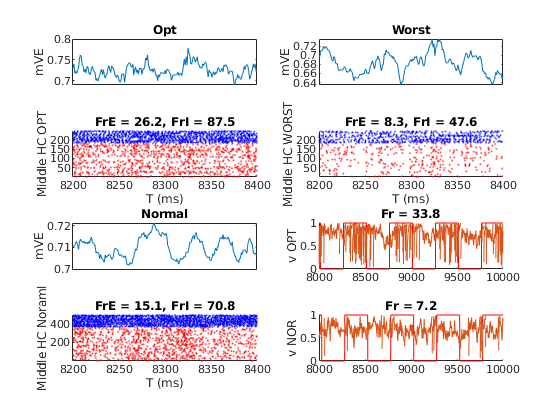

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColE = NnE.X>=1.25*n_E_HC & NnE.X<=1.75*n_E_HC;
MidRowE = NnE.Y>=1.25*n_E_HC & NnE.Y<=1.75*n_E_HC;
MidHCE = MidColE & MidRowE;

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

ShowWin = [8200 8400];
figure('Name','Domain Range')

OD1E = find(OptE & MidHCE);
OD1I = find(OptI & MidHCI);
scatter1E = find(ismember(SpE(:,1),OD1E));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1E_Ind] = ismember(SpE(scatter1E,1),OD1E);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1E,2),OD1E_Ind,0.5,'r.')
scatter(SpI(scatter1I,2),OD1I_Ind+max(OD1E_Ind),0.5,'b.');  
FrE1 = length(SpE(scatter1E,2))/(T/1e3)/length(OD1E);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrE = %.1f, FrI = %.1f',FrE1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVE(OD1E,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(WorstE & MidHCE);
OD2I = find(WorstI & MidHCI);
scatter2E = find(ismember(SpE(:,1),OD2E));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2E_Ind] = ismember(SpE(scatter2E,1),OD2E);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2E,2),OD2E_Ind,0.5,'r.')
scatter(SpI(scatter2I,2),OD2I_Ind+max(OD2E_Ind),0.5,'b.'); 
FrE2 = length(SpE(scatter2E,2))/(T/1e3)/length(OD2E);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrE = %.1f, FrI = %.1f',FrE2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC WORST')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

OD3E = find(NorE & MidHCE);
OD3I = find(NorI & MidHCI);
scatter3E = find(ismember(SpE(:,1),OD3E));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3E_Ind] = ismember(SpE(scatter3E,1),OD3E);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3E,2),OD3E_Ind,0.5,'r.')
scatter(SpI(scatter3I,2),OD3I_Ind+max(OD3E_Ind),0.5,'b.');  
FrE3 = length(SpE(scatter3E,2))/(T/1e3)/length(OD3E);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrE = %.1f, FrI = %.1f',FrE3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC Noraml')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Normal')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1E(50);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('Fr = %.1f',Fr1E1))
ylabel('v OPT')
subplot 428
hold on
NeuInd = OD2E(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('Fr = %.1f',Fr1E2))
ylabel('v NOR')
% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

### Plot Spatial maps: Plot

WinSize = 7500;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
OnOffmV = ~logical(floor(mod(...
                             repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), ...
                             tMod)/MaxOnPhase));
OnOffSpE =  ~logical(floor(mod(...
                               PhaseE(SpE(:,1)) - T + SpE(:,2),...
                               tMod)/MaxOnPhase));

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

Figure for ONOFF

First create an onoff vec for each spike

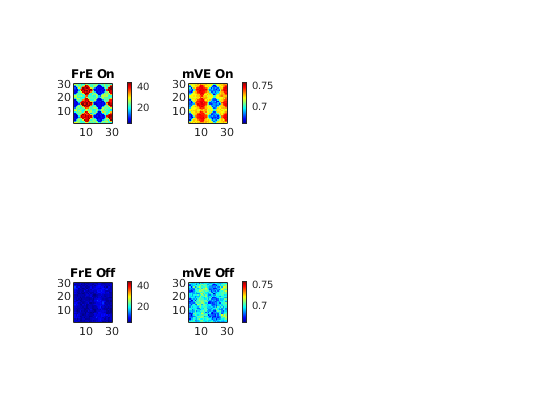

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrEOnPixMat,~] = NeuVec2Pixel(FrEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEOnPixMat); title('FrE On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis([5 45])
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrEOffPixMat,~] = NeuVec2Pixel(FrEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEOffPixMat); title('FrE Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis([5 45])
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs
OnmVPhase = double(OnOffmV);
OnmVPhase(~OnOffmV) = nan;
subplot 242
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

[mVEOnPixMat,~] = NeuVec2Pixel(mVEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEOnPixMat); title('mVE On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis([0.66 0.76])

OffmVPhase = double(~OnOffmV);
OffmVPhase(OnOffmV) = nan;
subplot 246
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

[mVEOffPixMat,~] = NeuVec2Pixel(mVEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEOffPixMat); title('mVE Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis([0.66 0.76])


% % mGs
% subplot 243
% GEEOn = GE_E; GEEOn = GEEOn.*OnmVPhase;
% GEEOn_temp = nanmean(GEEOn(:,SmallWinRange),2);
% [GEEOnPixMat,~] = NeuVec2Pixel(GEEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOnPixMat); title('GEE On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 247
% GEEOff = GE_E; GEEOff = GEEOff.*OffmVPhase;
% GEEOff_temp = nanmean(GEEOff(:,SmallWinRange),2);
% [GEEOffPixMat,~] = NeuVec2Pixel(GEEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOffPixMat); title('GEE Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 244
% GEIOn = GE_I; GEIOn = GEIOn.*OnmVPhase;
% GEIOn_temp = nanmean(GEIOn(:,SmallWinRange),2);
% [GEIOnPixMat,~] = NeuVec2Pixel(GEIOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOnPixMat); title('GEI On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 248
% GEIOff = GE_I; GEIOff = GEIOff.*OffmVPhase;
% GEIOff_temp = nanmean(GEIOff(:,SmallWinRange),2);
% [GEIOffPixMat,~] = NeuVec2Pixel(GEIOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOffPixMat); title('GEI Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])

Figure for All Average

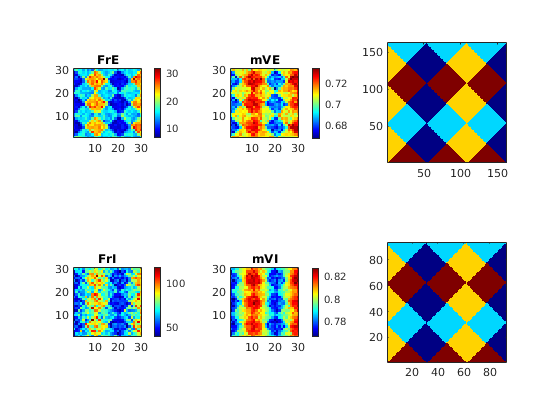

hFrVAll = figure('Name','Field_f&V');
subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot
OPT = find(OD_E == 1);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCount')

hSpCount =   Figure (4: SpCount) with properties:

      Number: 4
        Name: 'SpCount'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


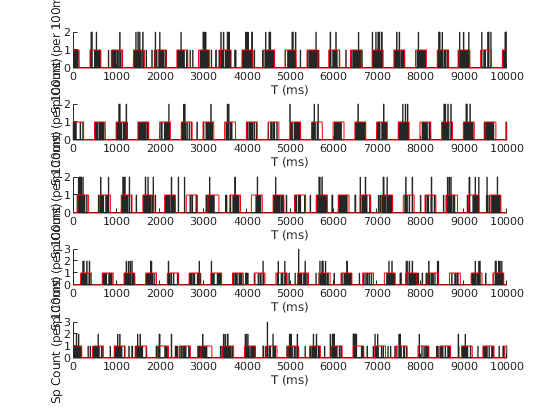

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(5,1,subInd)
    NeuInd = OPT(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([0 T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
end

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

PixNum = NPixX*N_HC * NPixY*N_HC;
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(PixNum);
C_EI_Pixel = zeros(PixNum);
C_IE_Pixel = zeros(PixNum);
C_II_Pixel = zeros(PixNum);
% look into std as well
C_EE_Pixelstd = zeros(PixNum);
C_EI_Pixelstd = zeros(PixNum);
C_IE_Pixelstd = zeros(PixNum);
C_II_Pixelstd = zeros(PixNum);
tic
AA = PixNum;
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc

Elapsed time is 51.260162 seconds.


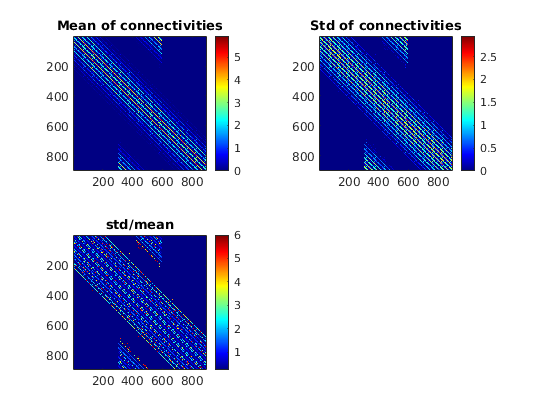

C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);
save([SaveFolder 'ConnPixel.mat'], 'C_EE_Pixel_Us','C_IE_Pixel_Us',...
                                   'C_II_Pixel_Us','C_EI_Pixel_Us')
% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

## Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
      C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
      ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

MF linear equation for pixels: 2 MF Eqns

load([SaveFolder 'ConnPixel.mat'])
C_EE_Pixel_Us = full(C_EE_Pixel_Us);
C_IE_Pixel_Us = full(C_IE_Pixel_Us);
C_EI_Pixel_Us = full(C_EI_Pixel_Us);
C_II_Pixel_Us = full(C_II_Pixel_Us);

PixNum = NPixX*N_HC * NPixY*N_HC;
FrEPixVec = reshape(FrEPixMat,PixNum,1);
FrEOnPixVec  = reshape(FrEOnPixMat,PixNum,1);
FrEOffPixVec = reshape(FrEOffPixMat,PixNum,1);
FrIPixVec = reshape(FrIPixMat,PixNum,1);

mVEPixVec = reshape(mVEPixMat,PixNum,1);
mVEOnPixVec  = reshape(mVEOnPixMat,PixNum,1);
mVEOffPixVec = reshape(mVEOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_EOn_Pixel = zeros(PixNum,1);
lambda_EOff_Pixel = zeros(PixNum,1);
L6E_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
for PixInd = 1:PixNum
    lambda_EOn_Pixel(PixInd)  = mean(lambda_EOn_drive(NnEPixel.Vec == PixInd));
    lambda_EOff_Pixel(PixInd) = mean(lambda_EOff_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + PixNum;
%FrPreUse = FrEOffPixVec(FrPreUseDim - PixNum); 
FrPreUse = FrEOffLIF(FrPreUseDim - PixNum); 
%FrPreUse = [];


% Mats
MatEE = (S_EE*(1-p_EEFail))*full(C_EE_Pixel_Us); % Need Ref here??
MatEI = S_EI *              full(C_EI_Pixel_Us);
MatIE = S_IE *              full(C_IE_Pixel_Us).*(Ve-repmat(mVIPixVec,1,PixNum));
MatII = S_II *              full(C_II_Pixel_Us).*(Vi-repmat(mVIPixVec,1,PixNum));
ConnMat = [MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEI.*(Vi-repmat(mVEOnPixVec,1,PixNum));
           MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEI.*(Vi-repmat(mVEOffPixVec,1,PixNum));
           MatIE/2                                    , MatIE/2                                    , MatII];
% Leak On/Off
LeakEOn  = gL_E * (0-mVEOnPixVec)  * 1e3;
LeakEOff = gL_E * (0-mVEOffPixVec) * 1e3;
LeakI =    gL_I * (0-mVIPixVec)    * 1e3;
LeakV = [LeakEOn;LeakEOff;LeakI];
% Ext
ExtEOn  = (lambda_EOn_Pixel*S_Elgn  + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOnPixVec ) * 1e3;
ExtEOff = (lambda_EOff_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOffPixVec) * 1e3;
ExtI =    (lambda_I_Pixel*S_Ilgn    + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec)    * 1e3;
ExtV = [ExtEOn;ExtEOff;ExtI];
% Ref Vec
RefEOn = 1-FrEOnPixVec*tau_ref/1e3;
RefEOff = 1-FrEOffPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = diag([RefEOn;RefEOff;RefI]);
% L4 Frs
Fr_L4 = [FrEOnPixVec; FrEOffPixVec; FrIPixVec];

% MF Equations:
%Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
    if isempty(FrPreUse)
    Fr_MFinv = (sparse(eye(3*PixNum))-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
    else
        FrPreVec = zeros(PixNum*3,1); FrPreVec(FrPreUseDim) = FrPreUse;
        DimAll = 1:PixNum*3; FrminusDim = DimAll(~ismember(DimAll,FrPreUse));
        FrPreReplace = RefM*ConnMat * FrPreVec; 
        % Now compute in the subspace
        FrPreMinus = FrPreReplace(FrminusDim);
        RefMMinus  = RefM(FrminusDim, FrminusDim);
        ConnMatMinus = ConnMat(FrminusDim, FrminusDim);
        ExtVMinus = ExtV(FrminusDim);
        LeakVMinus = LeakV(FrminusDim);
        Fr_MFinvMinus = (sparse(eye(length(FrminusDim)))-RefMMinus*ConnMatMinus) \ ...
                        (RefMMinus * ( ExtVMinus + LeakVMinus) + FrPreMinus);
        % make up MF output            
        Fr_MFinv = zeros(PixNum*3,1);   
        Fr_MFinv(FrminusDim) = Fr_MFinvMinus; Fr_MFinv(FrPreUseDim) = FrPreUse; 
    end
toc

Elapsed time is 0.438461 seconds.


% Err
FrErr = Fr_MFinv - Fr_L4;

Scatter MF Rslt

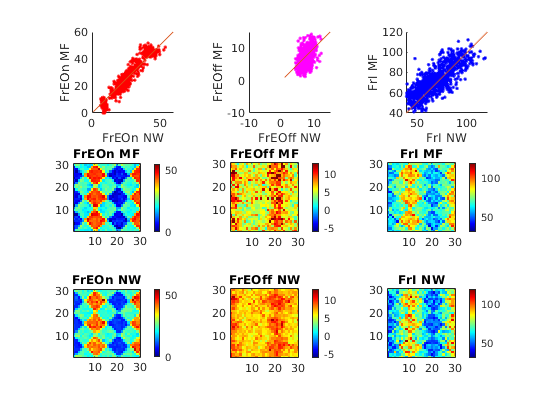

SC = Fr_MFinv;
figure('Name','FrCompare')
subplot 331
hold on
scatter(FrEOnPixVec, SC(1:900),'r.')
plot(1:120, 1:120)
axis([0 60 0 60]);axis square
xlabel('FrEOn NW'); ylabel('FrEOn MF')
subplot 332
hold on
scatter(FrEOffPixVec, SC(901:1800),'m.')
plot(1:120, 1:120)
axis([-10 15 -10 15]); axis square
xlabel('FrEOff NW'); ylabel('FrEOff MF')
subplot 333
hold on
scatter(FrIPixVec, SC(1801:2700),'b.')
plot(1:120, 1:120)
axis([40 120 40 120]); axis square
xlabel('FrI NW'); ylabel('FrI MF')

subplot 334
ShowField(SC(1:PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOn MF')
caxis([0 55])

subplot 335
ShowField(SC(PixNum+1:2*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOff MF')
caxis([-6 13])

subplot 336
ShowField(SC(2*PixNum+1:3*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI MF')
caxis([30 120])

subplot 337
ShowField(FrEOnPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOn NW')
caxis([0 55])

subplot 338
ShowField(FrEOffPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOff NW')
caxis([-6 13])

subplot 339
ShowField(FrIPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI NW')
caxis([30 120])

Plot MF Rslt

EPixRange = [0 35];
IPixRange = [10 120]

IPixRange =     10   120



figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = (reshape(Fr_MFinv(1:PixNum),NPixY*N_HC,NPixX*N_HC) + ...
               reshape(Fr_MFinv(PixNum+1:2*PixNum),NPixY*N_HC,NPixX*N_HC))/2;
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(2*PixNum+1:end),NPixY*N_HC,NPixX*N_HC)

FrIPixMat_MF =    57.5174   63.0698   55.5432   66.3625   62.0774   63.2833   78.1563   73.6559   74.2780   76.5193   82.4685   74.0214   86.4570   82.1942   78.6659   61.0353   63.8454   57.2478   73.2565   56.1803   50.3525   83.7832   64.6980   63.7243   73.9307   77.9816   76.4960   76.0131   65.6612   93.2106
   52.1740   51.9513   64.9112   71.1184   74.6255   79.7609   75.6300   78.5378   65.3953   95.5355   97.4058   83.1383   66.0687   65.8745   76.9803   67.5858   56.5174   78.1153   72.1356   38.4813   55.9720   54.9121   69.5097   72.2340   64.5688   73.0430   79.0307   67.6583   77.1496  100.7054
   56.2644   59.4527   64.1341   75.8825   80.1563   65.7453   56.2949   68.2711   88.6415  100.4216   86.5961   86.8667   76.4411   64.4357   71.1529   75.9881   63.2460   71.9534   39.6463   59.3373   62.2165   44.2721   59.3377   80.3444   75.9700   68.0096   60.4228   81.4272  105.9310   90.0829
   58.3902   65.5505   55.4074   60.7217   86.8437   70.3919   84.3087   99.4556  

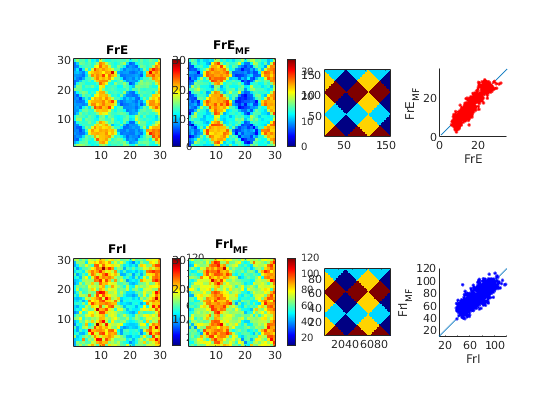

imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
hold on
plot(1:120, 1:120)
scatter(FrEPixVec,(Fr_MFinv(1:PixNum) + Fr_MFinv(PixNum+1:2*PixNum))/2,'r.')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_{MF}')

subplot 248
hold on
plot(1:120, 1:120)
scatter(FrIPixVec,Fr_MFinv(2*PixNum+1:end),'b.')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_{MF}')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?